%Error plots
%Obtain variance values
Cov_matrix = inv(A);
Var_values = diag(Cov_matrix);
newSize = size(T_op);
r_GT = r_i_vk_i(1:3,k1:k2);
theta_GT = theta_vk_i(1:3,k1:k2);

for i = 1:newSize(1,1)
    
    x_vals(i,1) = r_k(1,i)-r_GT(1,i);
    y_vals(i,1) = r_k(2,i)-r_GT(2,i);
    z_vals(i,1) = r_k(3,i)-r_GT(3,i);
    
    x_vals(i,2) = 3*sqrt(Var_values((i*6)-5,1));
    y_vals(i,2) = 3*sqrt(Var_values((i*6)-4,1));
    z_vals(i,2) = 3*sqrt(Var_values((i*6)-3,1));
    
    T = T_op{i,1};
    C = T(1:3,1:3);
    C_GT = vec2rot(-theta_GT(1:3,i));
    C_var = eye(3) - C*C_GT';
    ux =  mean([C_var(3,2), -C_var(2,3)]);
    uy =  mean([-C_var(3,1),C_var(1,3)]);
    uz =  mean([C_var(2,1), -C_var(1,2)]);
    
    xth_vals(i,1) = ux;
    yth_vals(i,1) = uy;
    zth_vals(i,1) = uz;
    
    xth_vals(i,2) = 3*sqrt(Var_values((i*6)-2,1));
    yth_vals(i,2) = 3*sqrt(Var_values((i*6)-1,1));
    zth_vals(i,2) = 3*sqrt(Var_values((i*6),1));
    
        
end

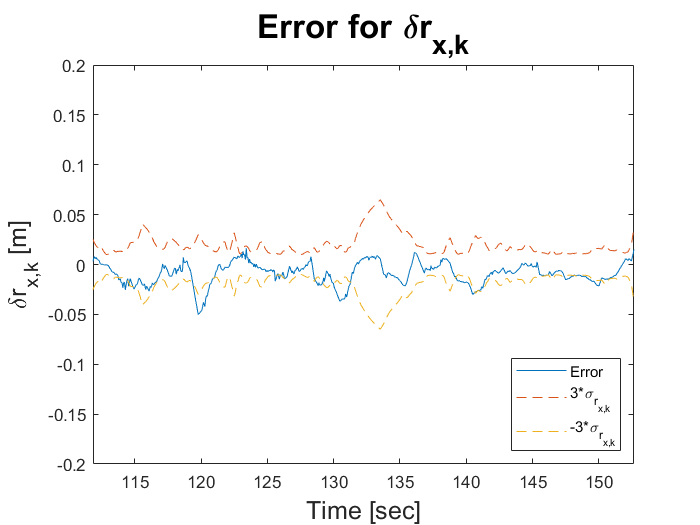

time = t(k1:k2);
y_limit1 = [-0.2,0.2];
y_limit2 = [-0.5,0.5];
figure
plot(time,x_vals(:,1),time,x_vals(:,2),'--',time,-x_vals(:,2),'--')
legend('Error','3*\sigma_{r_{x,k}}','-3*\sigma_{r_{x,k}}', 'Location','southeast')
xlim([t(k1),t(k2)])
ylim(y_limit1)
title('Error for \deltar_{x,k}','FontSize',20)
xlabel('Time [sec]','FontSize',15)
ylabel('\deltar_{x,k} [m]','FontSize',15)

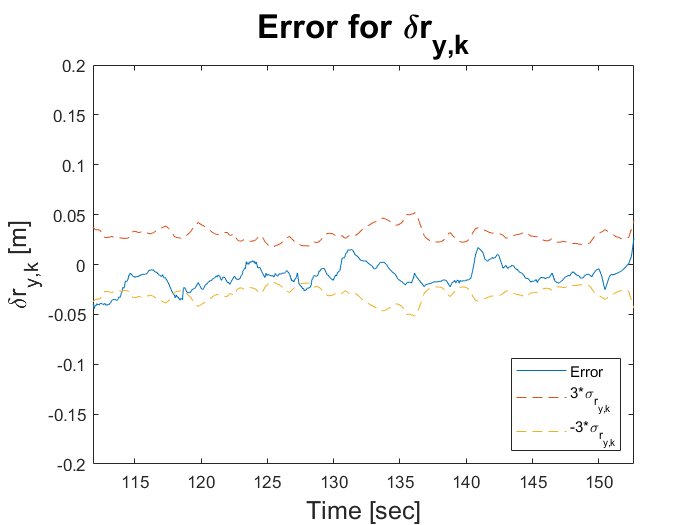

figure
plot(time,y_vals(:,1),time,y_vals(:,2),'--',time,-y_vals(:,2),'--')
legend('Error','3*\sigma_{r_{y,k}}','-3*\sigma_{r_{y,k}}', 'Location','southeast')
xlim([t(k1),t(k2)])
ylim(y_limit1)
title('Error for \deltar_{y,k}','FontSize',20)
xlabel('Time [sec]','FontSize',15)
ylabel('\deltar_{y,k} [m]','FontSize',15)

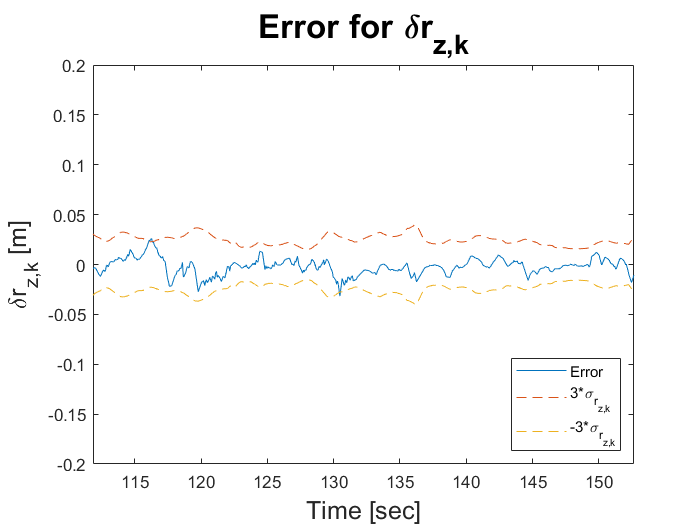


figure
plot(time,z_vals(:,1),time,z_vals(:,2),'--',time,-z_vals(:,2),'--')
legend('Error','3*\sigma_{r_{z,k}}','-3*\sigma_{r_{z,k}}', 'Location','southeast')
xlim([t(k1),t(k2)])
ylim(y_limit1)
title('Error for \deltar_{z,k}','FontSize',20)
xlabel('Time [sec]','FontSize',15)
ylabel('\deltar_{z,k} [m]','FontSize',15)

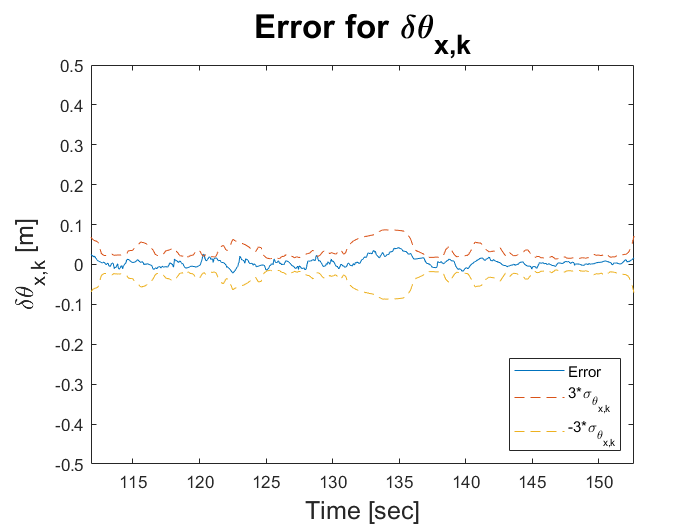

figure
plot(time,xth_vals(:,1),time,xth_vals(:,2),'--',time,-xth_vals(:,2),'--')
legend('Error','3*\sigma_{\theta_{x,k}}','-3*\sigma_{\theta_{x,k}}', 'Location','southeast')
xlim([t(k1),t(k2)])
ylim(y_limit2)
title('Error for \delta\theta_{x,k}','FontSize',20)
xlabel('Time [sec]','FontSize',15)
ylabel('\delta\theta_{x,k} [m]','FontSize',15)

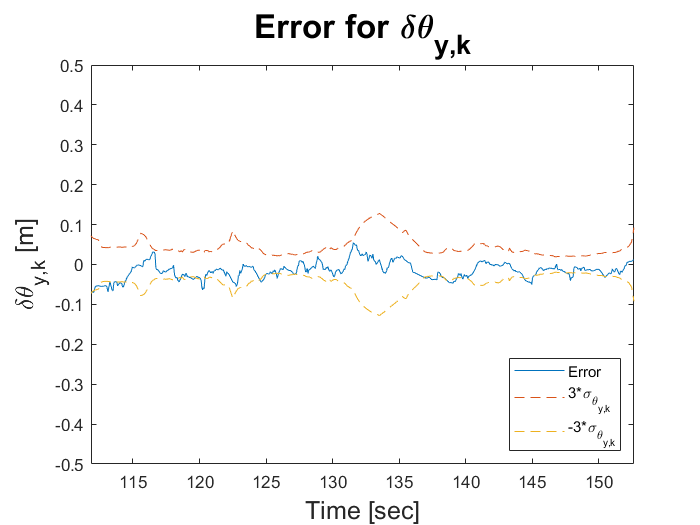

figure
plot(time,yth_vals(:,1),time,yth_vals(:,2),'--',time,-yth_vals(:,2),'--')
legend('Error','3*\sigma_{\theta_{y,k}}','-3*\sigma_{\theta_{y,k}}', 'Location','southeast')
xlim([t(k1),t(k2)])
ylim(y_limit2)
title('Error for \delta\theta_{y,k}','FontSize',20)
xlabel('Time [sec]','FontSize',15)
ylabel('\delta\theta_{y,k} [m]','FontSize',15)

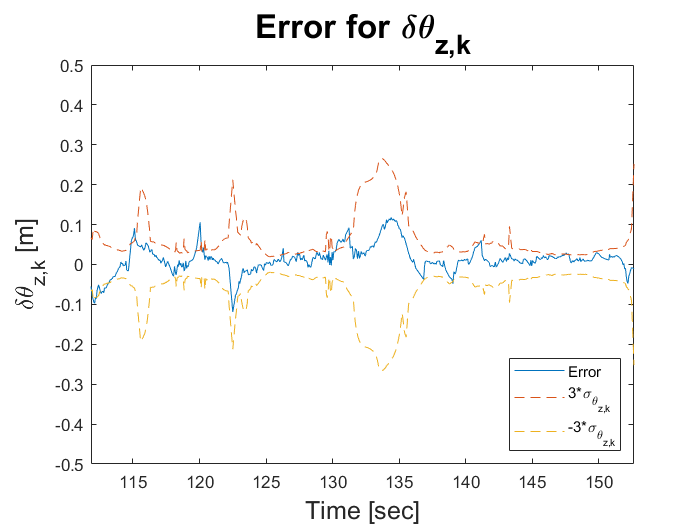

figure
plot(time,zth_vals(:,1),time,zth_vals(:,2),'--',time,-zth_vals(:,2),'--')
legend('Error','3*\sigma_{\theta_{z,k}}','-3*\sigma_{\theta_{z,k}}', 'Location','southeast')
xlim([t(k1),t(k2)])
ylim(y_limit2)
title('Error for \delta\theta_{z,k}','FontSize',20)
xlabel('Time [sec]','FontSize',15)
ylabel('\delta\theta_{z,k} [m]','FontSize',15)